# **Multiple point-Bayesian inference**

## **1 - INITIALIZE UQLAB**

clc;clear all;close all;
clearvars
rng(100,'twister')
uqlab

Copyright 2013-2022, Stefano Marelli and Bruno Sudret, all rights reserved.
This is UQLab, version 2.0
UQLab is distributed under the BSD 3-clause open source license available at: 
F:\onedrive\OneDrive - Imperial College London\PhD_Work\UQlab\UQLab_Rel2.0.0\UQLab_Rel2.0.0\LICENSE.

To request special permissions, please contact:
  - Stefano Marelli (<a href="mailto:marelli@ibk.baug.ethz.ch">marelli@ibk.baug.ethz.ch</a>).

Useful commands to get started with UQLab:
uqlab -doc           - Access the available documentation
uqlab -help          - Additional help on how to get started with UQLab
uq_citation help   - Information on how to cite UQLab in publications
uqlab -license       - Display UQLab license information



## 2 - Experiment desigh (Uniform LHS)

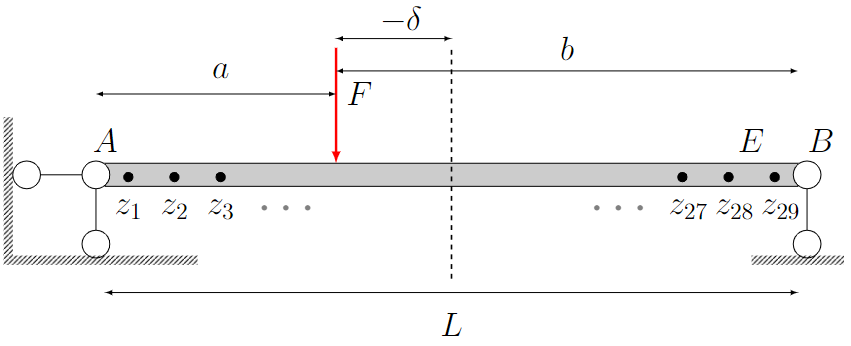

        b_b = 0.15; % beam width  (m)

        b_h = 0.3; % beam height (m)

        L = 30; % beam length (m)

**Computational model:**

$a = \frac{L}{2}- \delta$;$b = \frac{L}{2}+ \delta$


$$\mathcal{M}(\vec{\theta}) = \frac{F b  z  [(L^2 - b^2) - z^2]}{6LEI} \ \ \   \ \ \ \ \ \ \ z \le a$$
 


$$\mathcal{M}(\vec{\theta})  =  \frac{F b  [\frac{L}{b} (z - a)^3 + (L^2 - b^2)z-z^3]}{6LEI} \ \ \ \ z> a
$$



$$\vec{\theta} = [E,\delta,F,z];\vec{z} = [z_1,z_2,...,z_{28},z_{29}];$$


 $E $ is elastic modulus; $\delta$ is the loading postion, *F *is the loading force

$\vec{z} $is the different measurement points along the beam;

$\mathcal{M}$ is the FE model; $Y_i$ is the measurement data; $N$ is the number of experiment expNum.

Create a MODEL from the function file:

% %LHS sampling number

p = 1;
N = 500;


%E experiment design

E_lhs = lhsdesign(N, p, 'criterion', 'none');
lower_limit_E = 20e9;
upper_limit_E = 50e9;
E_Uniform_sample = lower_limit_E + E_lhs * (upper_limit_E - lower_limit_E);
size(E_Uniform_sample)

ans =    500     1


%delta experiment design

delta_lhs = lhsdesign(N, p, 'criterion', 'none');
lower_limit_delta = -5;
upper_limit_delta = 5;
delta_Uniform_sample = lower_limit_delta + delta_lhs * (upper_limit_delta - lower_limit_delta);
size(delta_Uniform_sample)

ans =    500     1


%  F experiment design

F_lhs = lhsdesign(N, p, 'criterion', 'none');
lower_limit_F =20000;
upper_limit_F = 60000;
F_Uniform_sample = lower_limit_F + F_lhs * (upper_limit_F - lower_limit_F);
size(F_Uniform_sample)

ans =    500     1


%Catenate E, delta and F
LHS_sample_total = [E_Uniform_sample delta_Uniform_sample F_Uniform_sample];	%

LHS_sample = LHS_sample_total(1:round(0.8*N),:);
LHS_validate = LHS_sample_total(round(0.8*N)+1:end,:);
size(LHS_sample)

ans =    400     3


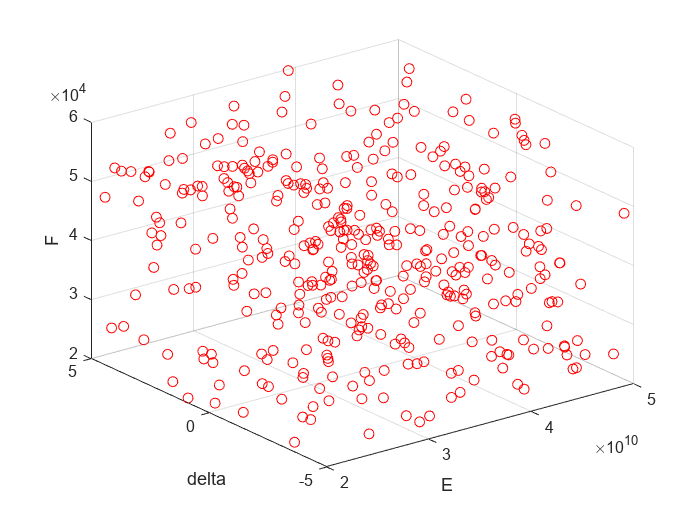

%plot LHS sampling
scatter3(LHS_sample(:,1),LHS_sample(:,2),LHS_sample(:,3),'r')
xlabel('E');ylabel('delta');zlabel("F");

Run FE simulation

FE_deflection = Deflection(LHS_sample);
size(FE_deflection)

ans =    400    29


FE_realization = [LHS_sample,FE_deflection];
size(FE_realization)

ans =    400    32


## 3 PCA reduce output dimensionality

Get the FE output

Y_Output = FE_realization(:,4:end);
size(Y_Output)

ans =    400    29


PCA reduction

[V,S,E,cumE,number]=princa(Y_Output,0.999)

V =     0.1845   -0.2477    0.2098    0.1605    0.1240   -0.1024    0.0795    0.0732    0.0586    0.0546    0.0478    0.0429    0.0911    0.2673    0.2318    0.1717    0.1619    0.3798    0.4169   -0.0404   -0.1456    0.0652    0.1882   -0.1300    0.1981   -0.2145    0.0217   -0.1544    0.3009
    0.1846   -0.2453    0.2027    0.1512    0.1148   -0.0937    0.0721    0.0660    0.0526    0.0489    0.0426    0.0381    0.0810   -0.1621    0.0425   -0.4777   -0.0338    0.0165   -0.3874   -0.3536   -0.1278   -0.1479    0.0130    0.2772    0.1468    0.0534   -0.0963   -0.3364    0.0208
    0.1846   -0.2413    0.1908    0.1354    0.0994   -0.0791    0.0597    0.0539    0.0425    0.0391    0.0339    0.0301    0.0639   -0.1347   -0.2854    0.3397   -0.1478   -0.0136    0.1939   -0.2733   -0.2859    0.0608   -0.1601   -0.0911   -0.2715    0.3856   -0.1854    0.1732   -0.2560
    0.1848   -0.2355    0.1737    0.1129    0.0774   -0.0581    0.0420    0.0366    0.0280    0.0252    0.0214    0.0187   

S =    -4.8467   -0.6183    0.0709    0.0114    0.0022   -0.0007    0.0001    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -4.8155   -0.0792   -0.0389   -0.0033    0.0010   -0.0006   -0.0001   -0.0001   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    1.4198    1.0539    0.0974   -0.0134    0.0021    0.0002   -0.0001    0.0001   -0.0001    0.0001   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    1.2360   -0.6042   -0.0214   -0.0118   -0.0022   -0.0003    0.0004    0.0002    0.0000   -0.0000   -0.0000   -0.0000   

E =    28.5303
    0.4658
    0.0038
    0.0001
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


cumE =     0.9838
    0.9999
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000


number = 2

save S;
save V;
save number;
save st;
save mv;

## 4 PCA truncation

Reconstruct the output

close all;
[m, n] = size(S);  % Gets the dimensions of S
mv = mean(Y_Output);  % The mean of the raw data
st = std(Y_Output);   % Standard deviation of the original data

Y_ouput_reconstructed = S(:, 1:number) * V(:, 1:number)';
% De-normalize the score for each principal component
for i = 1:size(Y_ouput_reconstructed, 2)
    Y_ouput_reconstructed(:, i) = Y_ouput_reconstructed(:, i) * st(i) + mv(i);
end

size(Y_ouput_reconstructed)

ans =    400    29


modelling error of PCA truncation

PCA_loss =abs(Y_Output - Y_ouput_reconstructed);
size(PCA_loss)

ans =    400    29


Cov_PCA_loss = cov(PCA_loss);
size(Cov_PCA_loss)

ans =     29    29


h = heatmap(Cov_PCA_loss)

h =   HeatmapChart - 属性:

        XData: {29×1 cell}
        YData: {29×1 cell}
    ColorData: [29×29 double]

  显示 所有属性


h.FontSize = 10

h =   HeatmapChart - 属性:

        XData: {29×1 cell}
        YData: {29×1 cell}
    ColorData: [29×29 double]

  显示 所有属性


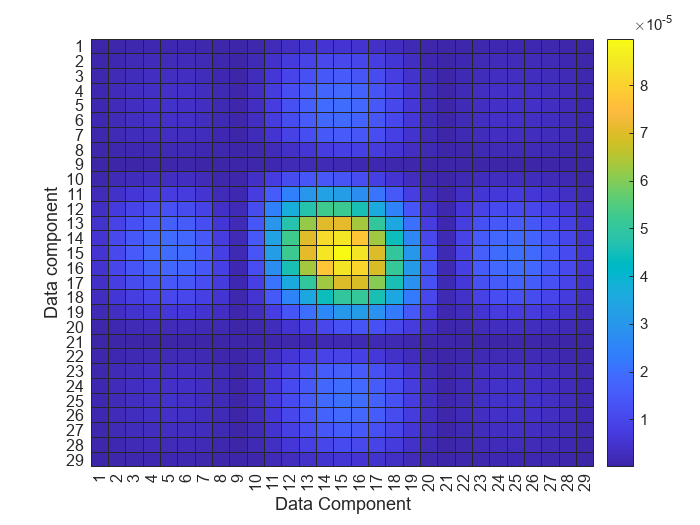

h =   HeatmapChart - 属性:

        XData: {29×1 cell}
        YData: {29×1 cell}
    ColorData: [29×29 double]

  显示 所有属性


xlabel('Data Component');
ylabel('Data component');
h.Colormap = parula

## 5 - PROBABILISTIC INPUT MODEL for PCE

Priors

InputOpts.Marginals(1).Type = 'Uniform';
minE = min(FE_realization(:,1))

minE = 2.0029e+10

maxE = max(FE_realization(:,1))

maxE = 4.9964e+10

InputOpts.Marginals(1).Parameters  = [minE maxE];

% Concentrated load loading position
InputOpts.Marginals(2).Type = 'Uniform';
mindelta = min(FE_realization(:,2))

mindelta = -4.9956

maxdelta = max(FE_realization(:,2))

maxdelta = 4.9904

InputOpts.Marginals(2).Parameters  = [mindelta maxdelta];

% Loading F
InputOpts.Marginals(3).Type = 'Uniform';
minF = min(FE_realization(:,3))

minF = 2.0008e+04

maxF = max(FE_realization(:,3))

maxF = 5.9992e+04


InputOpts.Marginals(3).Parameters  = [minF maxF];

myInput = uq_createInput(InputOpts);

## 6 - POLYNOMIAL CHAOS EXPANSION (PCE) METAMODELS $\tilde{\mathcal{M}}(r)$

Calculate the polynomial chaos expansion (PCE) coefficients.

Select PCE as the metamodeling tool in UQLab:

metaopts.Type = 'Metamodel';
metaopts.MetaType = 'PCE';

Select the sparse-favouring least-square minimization LARS for the 

PCE coefficients calculation strategy:

metaopts.Method = 'LARS';

Select the PCE options and create the PCE model:

metaopts.Degree = 2:15;

Experimental design

X = FE_realization(:,1:3);
Y = S(:, 1:number);
metaopts.ExpDesign.X = X;
metaopts.ExpDesign.Y = Y;

Calculation

myPCE = uq_createModel(metaopts);

---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients converged at polynomial degree 11 and qNorm 1.00 for output variable 1
Final LOO error estimate: 3.174382e-12
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients converged at polynomial degree 10 and qNorm 1.00 for output variable 2
Final LOO error estimate: 1.604419e-11
---                 Calculation finished!                               ---


Print a summary of the resulting PCE metamodel:

uq_print(myPCE, [1])

%------------ Polynomial chaos output ------------%
   Number of input variables:    3
   Maximal degree:               11
   q-norm:                       1.00
   Size of full basis:           364
   Size of sparse basis:         195
   Full model evaluations:       400
   Leave-one-out error:          4.0161850e-13
   Modified leave-one-out error: 3.1743818e-12
   Mean value:                   0.0037
   Standard deviation:           5.3122
   Coef. of variation:        143643.691%
%--------------------------------------------------%


Export the PCE strucuture

save myPCE

## 7 - Yval vs YPCE (Principle component)

Get the validation set 

FE_deflection_total = Deflection(LHS_sample_total);
size(FE_deflection_total)

ans =    500    29


FE_realization_total = [LHS_sample_total,FE_deflection_total];
size(FE_realization_total)

ans =    500    32


PCA processing

Xval = FE_realization_total(:,1:3);
size(Xval)

ans =    500     3


Yval_original = FE_realization_total(:,4:end);
size(Yval_original)

ans =    500    29


[V_val,S_val,E_val,cumE_val,number_val]=princa(Yval_original,0.999)

V_val =     0.1845   -0.2474    0.2092    0.1615    0.1227   -0.1014    0.0828    0.0712    0.0587    0.0535    0.0462    0.0498    0.0905    0.0097   -0.0481    0.0873    0.2971    0.0821    0.0226    0.0272   -0.2362    0.4784   -0.4875   -0.0164    0.1782    0.2404    0.2291    0.0224   -0.0845
    0.1846   -0.2450    0.2022    0.1521    0.1137   -0.0929    0.0752    0.0642    0.0527    0.0479    0.0412    0.0443    0.0805   -0.0076    0.0307   -0.2589   -0.1241    0.6186   -0.0897    0.1441    0.1938    0.0643    0.3252    0.2766   -0.1216    0.1668   -0.1673   -0.0396    0.0656
    0.1847   -0.2410    0.1904    0.1363    0.0985   -0.0784    0.0623    0.0525    0.0426    0.0383    0.0328    0.0350    0.0636   -0.0321   -0.1598    0.0072   -0.5356   -0.2398    0.2641   -0.1809   -0.0555    0.0370   -0.0928    0.0183   -0.3459   -0.2796    0.2211   -0.0990    0.2784
    0.1848   -0.2352    0.1734    0.1138    0.0767   -0.0577    0.0440    0.0357    0.0281    0.0247    0.0207    0.021

S_val =    -4.8615   -0.6265    0.0714    0.0118    0.0023   -0.0007    0.0002    0.0001    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
   -4.8291   -0.0876   -0.0379   -0.0036    0.0010   -0.0006   -0.0001   -0.0001   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
    1.4077    1.0609    0.1001   -0.0143    0.0024    0.0003   -0.0000    0.0001   -0.0001    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    1.2199   -0.5978   -0.0196   -0.0112   -0.0020   -0.0003    0.0004    0.0002    0.0000   -0.0000   -0.0000   -0.000

E_val =    28.5421
    0.4542
    0.0036
    0.0001
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


cumE_val =     0.9842
    0.9999
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000


number_val = 2

Evaluate the full model response at the validation sample points:

Yval = S_val(:, 1:number_val);

size(Yval)

ans =    500     2


Responses for PCE 

YPCE= uq_evalModel(myPCE,Xval);

Principle component modelling error

Error = (Yval - YPCE);
ErrorCov = cov(Error);
h = heatmap(ErrorCov)

h =   HeatmapChart - 属性:

        XData: {2×1 cell}
        YData: {2×1 cell}
    ColorData: [2×2 double]

  显示 所有属性



h.FontSize = 20

h =   HeatmapChart - 属性:

        XData: {2×1 cell}
        YData: {2×1 cell}
    ColorData: [2×2 double]

  显示 所有属性


xlabel('Data Component');
ylabel('Data component');
% orignal xy label
xLabels = h.XDisplayLabels;
yLabels = h.YDisplayLabels;

h.Colormap = parula

h =   HeatmapChart - 属性:

        XData: {2×1 cell}
        YData: {2×1 cell}
    ColorData: [2×2 double]

  显示 所有属性


Yval vs YPCE

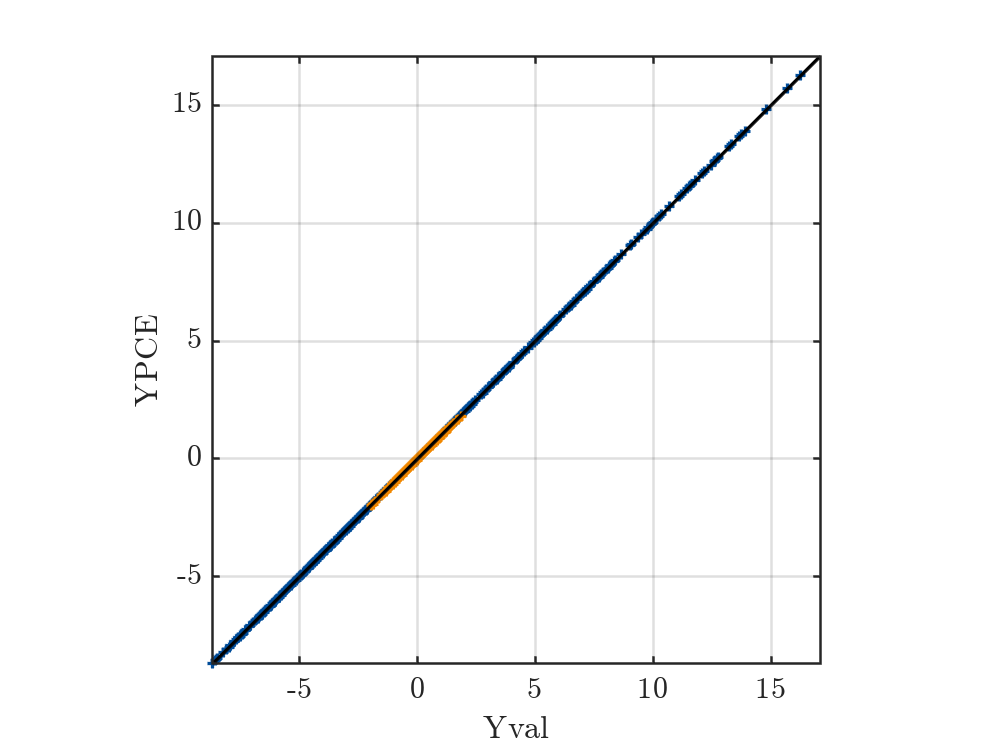

close all;
uq_figure
uq_plot(Yval, YPCE, '+')
hold on
uq_plot([min(Yval,[],'all') max(Yval,[],'all')], [min(Yval,[],'all') max(Yval,[],'all')], 'k')
hold off
axis equal
axis([min(Yval,[],'all') max(Yval,[],'all') min(Yval,[],'all') max(Yval,[],'all')])
xlabel('Yval');
ylabel('YPCE');
box on;

% 

## 8 - Modelling Error on PCs

Error = (Yval - YPCE);
ErrorCov = cov(Error);
h = heatmap(ErrorCov)

h =   HeatmapChart - 属性:

        XData: {2×1 cell}
        YData: {2×1 cell}
    ColorData: [2×2 double]

  显示 所有属性


h.FontSize = 20

h =   HeatmapChart - 属性:

        XData: {2×1 cell}
        YData: {2×1 cell}
    ColorData: [2×2 double]

  显示 所有属性


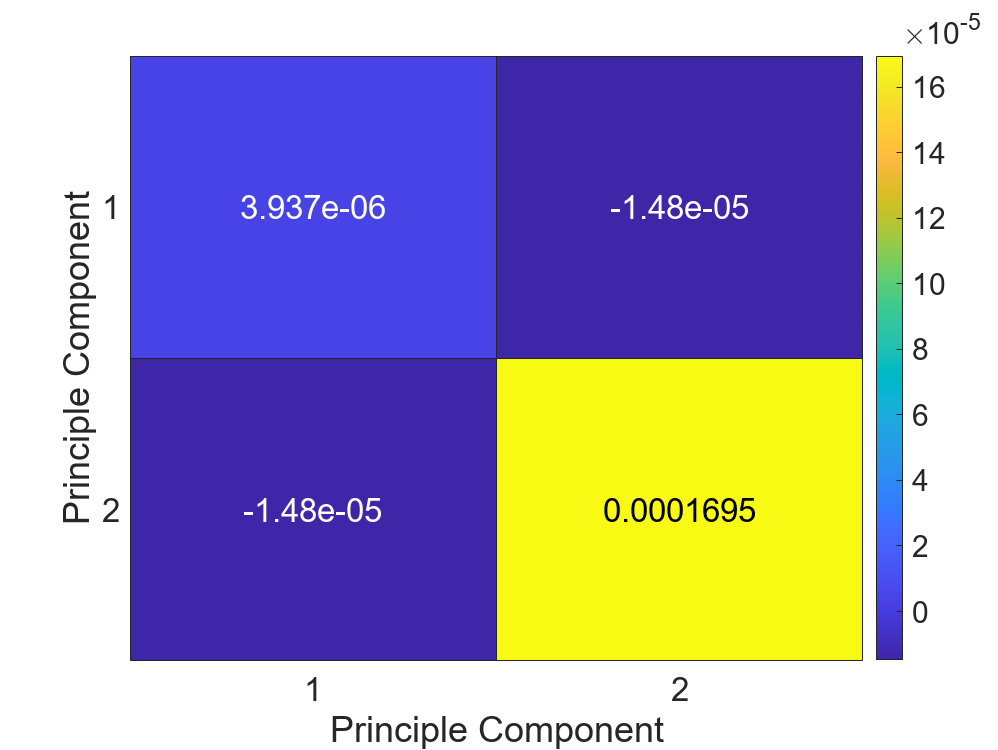

h =   HeatmapChart - 属性:

        XData: {2×1 cell}
        YData: {2×1 cell}
    ColorData: [2×2 double]

  显示 所有属性


xlabel('Principle Component');
ylabel('Principle Component');
h.Colormap = parula

## 9 - Modelling Error on Y-output

% %reconstruct the output

Yval_true = Yval_original;

size(Yval_true)

ans =    500    29



YPCE_true = YPCE(:, 1:number) * V(:, 1:number)';

for i = 1:size(YPCE_true, 2)
    YPCE_true(:, i) = YPCE_true(:, i) * st(i) + mv(i);
end

size(YPCE_true)

ans =    500    29


show the covariance matrix modelling error


Error = (Yval_true - YPCE_true);
ErrorCov = cov(Error);
h = heatmap(ErrorCov)

h =   HeatmapChart - 属性:

        XData: {29×1 cell}
        YData: {29×1 cell}
    ColorData: [29×29 double]

  显示 所有属性


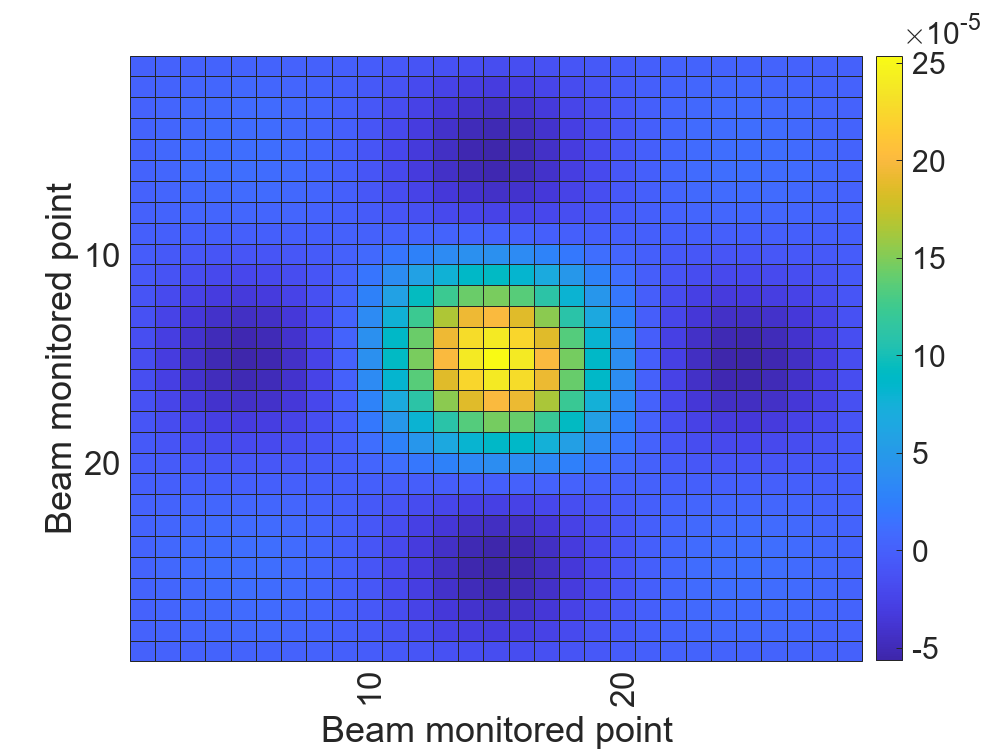

h =   HeatmapChart - 属性:

        XData: {29×1 cell}
        YData: {29×1 cell}
    ColorData: [29×29 double]

  显示 所有属性


h.FontSize = 20;
xlabel('Beam monitored point');
ylabel('Beam monitored point');
% orignal xy label
xLabels = h.XDisplayLabels;
yLabels = h.YDisplayLabels;

% ticks for 10  20 30
xLabelsToShow = cell(size(xLabels));
yLabelsToShow = cell(size(yLabels));

for i = 1:length(xLabels)
    if ismember(str2num(xLabels{i}), [10, 20, 30])
        xLabelsToShow{i} = xLabels{i};
    else
        xLabelsToShow{i} = '';
    end
end

for j = 1:length(yLabels)
    if ismember(str2num(yLabels{j}), [10, 20, 30])
        yLabelsToShow{j} = yLabels{j};
    else
        yLabelsToShow{j} = '';
    end
end

% x-y label
h.XDisplayLabels = xLabelsToShow;
h.YDisplayLabels = yLabelsToShow;
h.Colormap = parula

%caxis([0, 5e-3]);

## 10 - Define the priors for F and discrepancy $\sigma$

## **Note: priors for F are different from input models above**

By default, UQlab assumes an independent and identically distributed discrepancy

$\varepsilon \sim \mathcal{N}(0,\mu_{y}^2)$, with $\mu_{y} = \frac{1}{N}\sum_{i = 1}^{N}y_i$

#### synthetic ground truth with 3% noise 

E = 30e9;delta = -2; F = 30000N; noise =0.03

Measurement = GroundTruth(30e9,-2,30000,1,0.03);
size(Measurement)

ans =      1    29


 priors

%Priors on F
PriorOpts.Marginals(1).Name = 'E';               % Loading F
PriorOpts.Marginals(1).Type = 'Gaussian';
PriorOpts.Marginals(1).Moments = [30e9 5e9];   % (N)
PriorOpts.Marginals(1).Bounds = [10e9 50e9];

PriorOpts.Marginals(2).Name = 'delta';               % Loading F
PriorOpts.Marginals(2).Type = 'Gaussian';
PriorOpts.Marginals(2).Moments = [0 3];   % (N)
PriorOpts.Marginals(3).Bounds = [-9 9];

PriorOpts.Marginals(3).Name = 'F';               % Loading F
PriorOpts.Marginals(3).Type = 'Gaussian';
PriorOpts.Marginals(3).Moments = [43000 5000];   % (N)
PriorOpts.Marginals(3).Bounds = [20000 60000];


PriorOpts.Marginals(4).Name = 'Sigma2';               % Loading F
PriorOpts.Marginals(4).Type = 'Uniform';
sigma2 = mean(Measurement(:,:),"all");
PriorOpts.Marginals(4).Moments = [0 sigma2.^2];


%define the discrepancy hyperparameters
% 
% 
% for i = 2:4
%     PriorOpts.Marginals(i).Type = 'Uniform';
%     PriorOpts.Marginals(i).Parameters = [-100 100];
% end


% PriorOpts.Marginals(5).Type = 'Uniform';
% PriorOpts.Marginals(5).Parameters = [0 5];



myPriorDist = uq_createInput(PriorOpts);
% 
% SigmaOpts.Marginals(1).Name = 'Sigma2';
% SigmaOpts.Marginals(1).Type = 'Uniform';
% sigma2 = mean(Measurement(:,:),"all");
% SigmaOpts.Marginals(1).Parameters = [0 sigma2.^2];
% 
% mySigmaDist = uq_createInput(SigmaOpts);
% DiscrepancyOptsUnknownDisc.Type = 'Gaussian';
% DiscrepancyOptsUnknownDisc.Prior = mySigmaDist;

## 11 - Define the custom-loglikelihood  and measurement data for UQlab calculation


$$\ell\mathcal{L} ({\vec{\theta}},{\epsilon} \mid {Y}) = \prod_{i=1}^{N}\frac{1}{(2\pi)^{{3}/2}\det({\Sigma}(\epsilon))^{1/2}}\exp\left(-\frac{1}{2}\left({Y_i} - \mathcal{M}(\vec{\theta})\right)^{{T}} {\Sigma}(\epsilon)^{-1}\left({Y_i} - \mathcal{M}(\vec{\theta})\right)\right)$$



myData.y = Measurement;
size(myData.y)

ans =      1    29


myData.Name = 'Measurement on 29 points along the beam';

Loglikelihood still follows the Gaussian discrepancy criteria

myLogLikeli = @(params,y) myLogLikeli_F(params,y);

## 12 - Solver options


Solver.Type = 'MCMC';
Solver.MCMC.Visualize.Parameters = [1 2 3 4];
Solver.MCMC.Visualize.Interval = 20;
Solver.MCMC.Sampler = 'AIES';
Solver.MCMC.Steps = 500;
Solver.MCMC.NChains = 10;
%Solver.MCMC.Proposal.PriorScale = 1e-3;

## 13 - Bayesian inference

%BayesOpts.Discrepancy = DiscrepancyOptsUnknownDisc;
%BayesOpts.ForwardModel.Model = myPCE;
BayesOpts.LogLikelihood = myLogLikeli;
BayesOpts.Data = myData;
BayesOpts.Type = 'inversion';
BayesOpts.Solver = Solver;
BayesOpts.Prior = myPriorDist;
BayesAnalysis = uq_createAnalysis(BayesOpts);


Starting AIES...



|                              |   0.60%

## 14 - Post-processing

Burn in 70%; 


badChainsIndex = squeeze(BayesAnalysis.Results.Sample(end,1,:) <-20000);

uq_postProcessInversionMCMC(BayesAnalysis,'pointEstimate','mean','percentiles',[0.05,0.95],'burnin',0.7,'badChains',badChainsIndex);

uq_print(BayesAnalysis);
%uq_postProcessInversion(BayesAnalysis,'priorPredictive',1000);
uq_display(BayesAnalysis);

## 15 - print the covariance

%hold off;
close all;
Mean_paramters = BayesAnalysis.Results.PostProc.Percentiles.Mean(:);
size(Mean_paramters)

calculate the autocorrelation coeficients-Matern function

% h = [];% spatial length
% R = [];% autocorrelation coeficients
% hyper_parameters = Mean_paramters(2:9);
% size(hyper_parameters)
% for i  = 1:29
%     for j = 1:29
%                 h = abs(i-j);
%                 if i ==j
%                     R(i,j) = (1+  5^0.5*h/hyper_parameters(8)  +   5*h^2/3/hyper_parameters(8)^2)*exp(-5^0.5*h/hyper_parameters(8));
% 
%                 else
% 
%                   R(i,j) = 0 ;
%                 end
%     end
% 
% end

Calculate the diagonal Std

% 
% Std_covariance = [];
% for i = 1:29
%     xi = 2*(i-1)/(29-1) -1;
%     Sum_legendre = 0;
%     %summary of the legendre functions
%     for j = 1:7
%         Basis_legendre = legendreP(j-1,xi);
%         %disp(Basis_legendre)
%         Sum_legendre = Sum_legendre +  hyper_parameters(j)*Basis_legendre;
% 
%     end
% 
%     Std_covariance(i) = Sum_legendre;
% 
% end

Calculate the Non-diagnoal covariance

% 
% Non_diagonal_Cov = [];
% for i = 1:29
%     for j = 1:29
%         Non_diagonal_Cov(i,j) = Std_covariance(i)*Std_covariance(j)*R(i,j);
%     end
% end

Print the Non-diggonal covariance

% heatmap(Non_diagonal_Cov)

## 16 -  90% error band on predictive posterior

### 90% confidence interval for E and $\delta$

set 90%  = 95%- 5%


uq_postProcessInversionMCMC(BayesAnalysis,'percentiles',[0.05,0.95]);

Obtained the lower bound and upper bound for E and $\delta$

F_5_LowB = BayesAnalysis.Results.PostProc.Percentiles.Values(1,1);
disp(F_5_LowB)

F_95_UpperB = BayesAnalysis.Results.PostProc.Percentiles.Values(2,1);
disp(F_95_UpperB)



N_predict = 10

% sampling on F
F_90_sample_O = linspace(F_5_LowB,F_95_UpperB,N_predict)';
size(F_90_sample_O)

%Shuffle the order 
shuffledIndices = randperm(length(F_90_sample_O));
F_90_sample = F_90_sample_O(shuffledIndices);
size(F_90_sample)



%plot the sampling on F
figure
histogram(F_90_sample)

Predictive FE realization

Predict_sample = [F_90_sample];
size(Predict_sample)

%Loop to get the predictive FE deflection

YPCE_Predict = [];

for i = 1:N_predict
    
    Xval_Predict = Predict_sample(i,:);   

    PCA_PCE = uq_evalModel(myPCE,Xval_Predict);
    Deflection = PCA_PCE*coeff';
    YPCE_Predict = [YPCE_Predict;Deflection];


end

size(YPCE_Predict)

Spline curve fitting to smooth the line for the 90CI

x = 1:29;%29 measurement position along the beam

for i = 1:size(YPCE_Predict,1)
    
    P = polyfit(x,YPCE_Predict(i,:),3);
    xi = 1:0.1:29;
    YPCE_Predict_Poly(i,:) = polyval(P,xi);
end
size(YPCE_Predict_Poly)

Loop to fill the error band 90%CI

%loop to fill the error band
close all;

for i = 1:size(YPCE_Predict_Poly,1)-1
    hold on;
    fill([xi fliplr(xi)], [-YPCE_Predict_Poly(i,:) fliplr(-YPCE_Predict_Poly(i+1,:))], 'cyan', 'FaceAlpha', 1,'EdgeColor','none');
end

 hold on;
 
 xlabel('Beam length \it{L} \rm(m)','FontSize',10);
 pbaspect([1 0.3 1]);
 ax = gca;
 ax.XAxisLocation = 'top';
 ylabel('Deflection (m)','FontSize',10);
 box on;
 set(ax,'FontSize',10);
 yticks('auto');
 ylim([-3.5 0])

scatter the measurement

x = 1:1:29;
size(x)

for i = 1: size(myData.y,1)
    scatter(x,-myData.y(i,:),'black','x');
    hold on;
end

draw the mean value of 90%CI

plot(xi,-mean(YPCE_Predict_Poly),'red','LineWidth',1.5);

legend

rectangle('Position', [22, -2.5,0.5, 0.25], 'FaceColor', 'cyan');
text(23, -2.35, '90% CI', 'FontSize', 8);
text(22.15, -2.7, 'x  measurement points', 'FontSize', 8);

line([22,22.6],[-3,-3],'linestyle','-','color','red','LineWidth',1.0);
text(23, -3, 'mean', 'FontSize', 8);

Plot the predictive individual lines

hold off;

% beam position

x_beam = 1:1:29

for i = 1:size(YPCE_Predict,1)
    
    plot(x_beam,-YPCE_Predict(i,:));
    hold on;
end
 xlabel('Beam length \it{L} \rm(m)','FontSize',10);
 pbaspect([1 0.3 1]);
 ax = gca;
 ax.XAxisLocation = 'top';
 ylabel('Predictive deflection (m)','FontSize',10);
 box on;
 set(ax,'FontSize',10);
 yticks('auto');
  yticks('auto');
 ylim([-3.5 0])